## Load Data

clear
clf
clc

orl_data = load('orl_data.mat');
orl_data = orl_data.data;
orl_lbls = load('orl_lbls.mat');
orl_lbls = orl_lbls.lbls;

%One sample of the data.
img1 = orl_data(:,80)

img1 =     0.4506
    0.4493
    0.4415
    0.4309
    0.3835
    0.3687
    0.3362
    0.2535
    0.2315
    0.2200


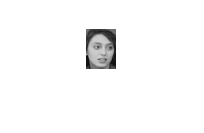

imshow(reshape(img1, [40, 30]))


%Pre allock
train_images = zeros(1200, 280);
test_images = zeros(1200, 120);

train_labels = zeros(280,1);
test_labels = zeros(120,1);

for i = 0:39
    p = randperm(10); %Random slice
    train_images(:,(i*7+1):((i+1)*7)) = orl_data(:,p(1:7)+i*10); %Take from 1 to 7.
    train_labels((i*7+1):((i+1)*7)) = orl_lbls(p(1:7)+i*10);
    test_images(:,(i*3+1):((i+1)*3)) = orl_data(:,p(8:10)+i*10); % Use the rest for test.
    test_labels((i*3+1):((i+1)*3)) = orl_lbls(p(8:10)+i*10);
end

%One sample of the data.
img1 = train_images(:,1)

img1 =     0.1874
    0.1695
    0.1576
    0.2450
    0.2266
    0.3070
    0.3784
    0.4194
    0.4776
    0.5339


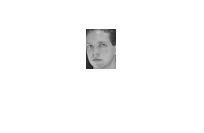

imshow(reshape(img1, [40, 30]))

## PCA

all_images = [train_images test_images];

[train_pca,test_pca] = pcaManual(all_images,train_images,test_images)

train_pca =    10.6447    9.6305   10.1287    9.6972   10.2010   10.5618   10.1333    8.2576    8.2000    7.8753    8.0611    7.3283    8.4569    7.9904    9.9823   10.4732   10.6061   10.8958    9.6935    8.3539   10.6775    9.5588   11.0783   10.9690   10.9356    9.3014    9.4619   10.7665   11.5503    9.7077    9.5160    9.2164   11.2607   11.3796   11.5868   13.8951   13.4946   13.7969   12.1405   13.9526   13.8842   13.6331   10.8549   10.8115    9.4948   10.7840   11.0614   11.0913   11.1411    9.8911
   13.8932   14.1129   13.6999   14.2603   15.3841   12.5576   14.4910   11.0884   11.6685   12.3437   11.4528   11.5904   11.6933   11.9701   10.5110   11.3494   11.1290   11.1382   10.6963   12.0289   10.8154   10.5267   10.5189   11.0278   11.1175   10.7988   10.9621   10.9384   12.8163   12.1971   12.0719   12.1957   12.8268   12.4380   12.3914   10.3647   10.2241   10.3379    9.3737   10.3040   10.2548   10.4710    9.2426    9.6610    9.3562   10.7718    9.7614    9.5742   10.0

test_pca =    10.6806   10.7291   10.3949    8.1077    8.1543    8.2894   11.0189    9.9529    8.7825    9.9558   10.1102    9.9198   11.4186   10.2148    9.2432   12.2047   11.8762   13.8941   10.8235   11.2310   10.3271   11.1042    9.7791   10.2620   10.5435   10.3270   11.1837   12.3955   11.1032   12.1579    7.3725    8.1628    7.6640   10.5891    9.2234   10.8188    9.5148    9.6675    8.3327    5.5851    5.3612    5.1904    8.1341    9.5679    8.0307    8.9151    9.4829    8.4668    9.2874   11.4029
   14.8459   14.1733   14.0191   11.8616   12.2710   11.5160   10.8768   10.9294   11.8058   10.3002   12.1099   10.3359   13.0534   12.0088   11.9330    9.5049    9.3217   10.3068    9.4964   10.2450    9.8061   11.2600   10.5403   11.9965    9.3513    9.1009    8.9729    7.4298    7.8411    8.5760   10.4825    8.6445    9.5414   13.0951   12.0376   13.0916   13.9660   13.9273   13.8789   11.8044   12.0034   12.7861   10.1591    9.8748   10.6611   12.0774   12.0876   15.5303   11.78

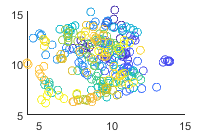


% Plot the data
scatter(train_pca(1,:),train_pca(2,:),[],train_labels)

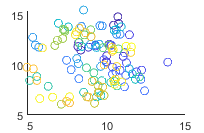

scatter(test_pca(1,:),test_pca(2,:)  ,[],test_labels)

## Nearest Class Centroid Classifier

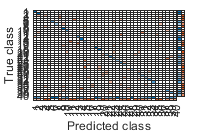

Overall accuracy: 39.1667%


%Pca data
class_labels = nearestClassCentroidClassifierORL(train_labels, train_pca, test_pca);
plotconfusionMatrixManual(test_pca, test_labels, class_labels)

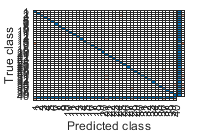

Overall accuracy: 93.3333%



%Real data
class_labels = nearestClassCentroidClassifierORL(train_labels, train_images, test_images);
plotconfusionMatrixManual(test_images, test_labels, class_labels)

## Nearest Sub-Class Centroid Classifier 2

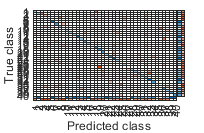

Overall accuracy: 40.8333%


%Pca data
tic
class_labels = NearestSubClassCentroidClassifierORL(train_labels, train_pca, test_pca,2);
plotconfusionMatrixManual(test_pca, test_labels, class_labels')

toc

Elapsed time is 0.802422 seconds.


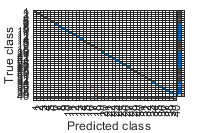

Overall accuracy: 94.1667%



%Real data
tic
class_labels = NearestSubClassCentroidClassifierORL(train_labels, train_images, test_images,2);
plotconfusionMatrixManual(test_images, test_labels, class_labels')

toc

Elapsed time is 1.109211 seconds.


**Nearest Sub-Class Centroid Classifier 3**

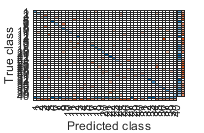

Overall accuracy: 40%


%Pca data
class_labels = NearestSubClassCentroidClassifierORL(train_labels, train_pca, test_pca,3);
plotconfusionMatrixManual(test_pca, test_labels, class_labels')

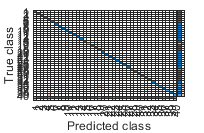

Overall accuracy: 94.1667%



%Real data
class_labels = NearestSubClassCentroidClassifierORL(train_labels, train_images, test_images,3);
plotconfusionMatrixManual(test_images, test_labels, class_labels')

**Nearest Sub-Class Centroid Classifier 5**

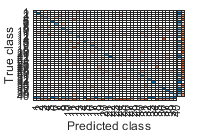

Overall accuracy: 40.8333%


%Pca data
class_labels = NearestSubClassCentroidClassifierORL(train_labels, train_pca, test_pca,5);
plotconfusionMatrixManual(test_pca, test_labels, class_labels')

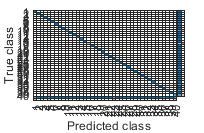

Overall accuracy: 94.1667%



%Real data
class_labels = NearestSubClassCentroidClassifierORL(train_labels, train_images, test_images,5);
plotconfusionMatrixManual(test_images, test_labels, class_labels')

## Nearest Neighbor classifier

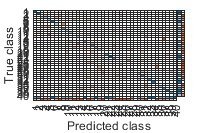

Overall accuracy: 40%


%Pca
class_labels = NearestNeighborClassifier(train_labels, train_pca, test_pca);
plotconfusionMatrixManual(test_pca, test_labels, class_labels)

Overall accuracy: 94.1667%



%Real data
class_labels = NearestNeighborClassifier(train_labels, train_images, test_images);
plotconfusionMatrixManual(test_pca, test_labels, class_labels)

## Perceptron with backpropagation

nDOT     = 10^(-3);
max_runs = 600;
%Pca
result = perceptron_with_back(train_pca,train_labels,nDOT,max_runs)

bincounts =      7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7


result =     0.0900   -0.7633    0.7861   -0.2329   -0.1001    2.0266   -1.0630    0.2331    0.4327    0.8177   -0.2085   -1.0744   -0.5088   -0.7311    0.1134   -0.1069    0.4640   -0.2095   -0.8811    0.2319    0.0351   -0.7248    0.6159   -1.1204   -0.3555   -1.0660   -0.7401   -1.2907    0.3865    1.2723   -0.4347   -1.6162    0.2349   -2.9947   -0.7635    0.3311   -2.7047    0.9408   -1.1889   -0.6078
    0.3300    0.5343   -0.6714   -0.4484   -0.1695   -1.5958   -1.4939   -0.0541   -0.4770   -1.1469    0.2726   -1.4089    0.1174    0.4695   -0.0001    0.2519   -0.1985   -0.0402    0.1861   -1.0560   -1.0496    0.2850   -1.0613   -1.8239   -0.1536   -0.4452    0.4157   -0.0459   -2.2609   -2.4677   -0.3630   -0.8174   -3.0397    0.6758   -0.1034   -1.3410    0.4403   -3.0512   -1.5434   -0.9290
   -4.5790   -0.2640   -1.1100   -0.3860   -0.2580   -1.5940   -2.8590   -1.0760   -0.0620   -0.0630   -1.7800   -4.2020   -1.1470   -0.0680   -1.3760   -1.3380   -0.8210   -0.3970   -0.817


%Real data
result = perceptron_with_back(train_images,train_labels,nDOT,max_runs)

bincounts =      7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7


result =     0.3356    0.2422    0.9738    1.1100    1.1276    0.9866    0.1740    0.8609    0.6093    0.8131    0.1997    0.5235    0.5623    0.2201    0.2545    0.2052    0.0423    0.5151    0.2374    0.4997    0.4797    0.3870    0.4577    0.0808    0.5653    0.4732    0.1578    0.4069    0.4869    0.4839    0.4291    0.1200    0.4041    0.1970    0.3670    0.1118    0.4433    0.3363    0.4151    0.5019
    0.3335    0.2906    1.0173    1.1520    1.1684    1.0161    0.2147    0.8699    0.6302    0.8038    0.2234    0.5519    0.5825    0.2441    0.2669    0.2230    0.0697    0.5278    0.2699    0.5056    0.4852    0.3979    0.4624    0.0867    0.5696    0.4786    0.1706    0.4132    0.4822    0.4749    0.4371    0.1225    0.4143    0.2046    0.3677    0.1088    0.4498    0.3322    0.4157    0.5042
    0.3326    0.3371    1.0666    1.1915    1.2194    1.0460    0.2688    0.8794    0.6582    0.8079    0.2489    0.5381    0.6117    0.2700    0.2863    0.2513    0.0961    0.5448    0.294

## Perceptron LMS

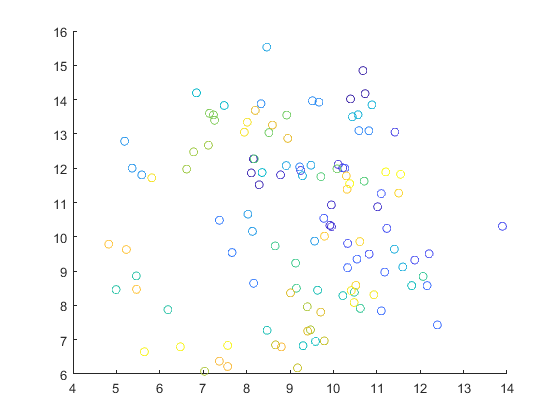

%Pca data
w = Perceptron_LMS_ORL(train_labels, train_pca);

figure
scatter(test_pca(1,:),test_pca(2,:),[],test_labels)
hold on
for i = 1:size(w,2)
    plotpc(w(2:end,i)',w(1,i));
end
hold off


plots_perceptronForORL(train_pca,train_labels,w)

Overall accuracy: 97.5%


%Real data
w = Perceptron_LMS_ORL(train_labels, train_images);

plots_perceptronForORL(test_images,test_labels,w)

Overall accuracy: 99.5%
